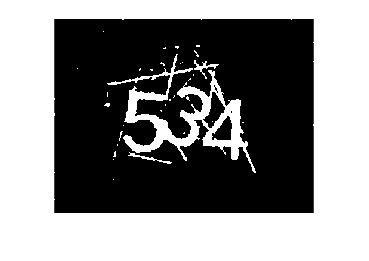

    I = imread("Train\captcha_0011.png");
    I_gray = rgb2gray(I);
    
    
    %Fourier transform
    fft = fft2(double(I_gray));
    fftshifted = fftshift(fft);
    
    magnitude = log(abs(fftshifted) + 1);    
    size_image = size(magnitude);
    
    tan_min = tan(deg2rad(66));
    tan_max = tan(deg2rad(67));
    
    for i = 1:size_image(1)
        for j = 1:size_image(2)
            tangent = (j - round(0.5 * size_image(2)))/(i - round(0.5 * size_image(1)));
            if tangent > tan_min  && tangent < tan_max
                fftshifted(i,j) = 0;
            end
        end
    end
    
    magnitude = log(abs(fftshifted) + 1);
    
    ifftshifted = ifftshift(fftshifted);
    res = uint8(ifft2(ifftshifted));
    
    %Binarization
    I_binary = imbinarize(res);
    I_binary = ~I_binary;
    % figure;
    imshow(I_binary)

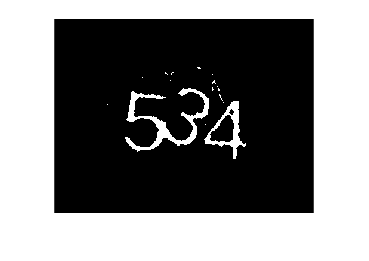

    
    %Erosion
    se = strel("diamond",3);
    I_eroded = imerode(I_binary,se);
    % figure;
    imshow(I_eroded)

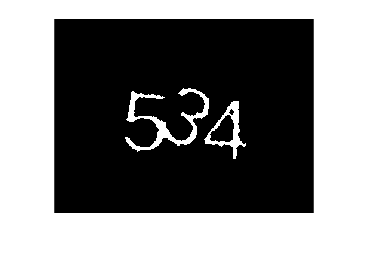


    I_open = bwareaopen(I_eroded, 400);
    % figure;
    imshow(I_open)

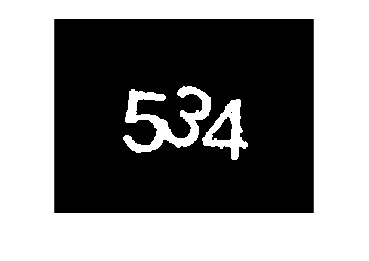

    
    %Dilation
    se = strel("disk",4);
    I_dilated = imdilate(I_open,se);
    figure;
    imshow(I_dilated)

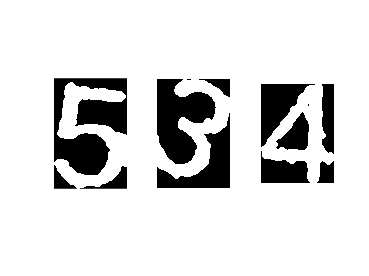


    count = bwconncomp(I_dilated,8);
    props = regionprops(count, 'Image');

    if count.NumObjects == 1
        [h,w] = size(props(1).Image);
        split = round(w/3);
        split1 = imcrop(props(1).Image,[0 0 split h]);
        split2 = imcrop(props(1).Image,[split 0 split h]);
        split3 = imcrop(props(1).Image,[split*2 0 split h]);
        
        figure;
        subplot(1,3,1);
        imshow(split1);
        subplot(1,3,2);
        imshow(split2);
        subplot(1,3,3);
        imshow(split3);
       
    elseif count.NumObjects == 2
        [h1,w1] = size(props(1).Image);
        [h2,w2] = size(props(2).Image);
        if w1 > w2 % Split first image
            split1 = imcrop(props(1).Image,[0 0 round(w1/2) h1]);
            split2 = imcrop(props(1).Image,[round(w1/2) 0 round(w1/2) h1]);
            split3 = props(2).Image;
        else % Split second image
            split1 = props(1).Image;
            split2 = imcrop(props(2).Image,[0 0 round(w2/2) h2]);
            split3 = imcrop(props(2).Image,[round(w2/2) 0 round(w2/2) h2]);
        end
        
        figure;
        subplot(1,3,1);
        imshow(split1);
        subplot(1,3,2);
        imshow(split2);
        subplot(1,3,3);
        imshow(split3);

    elseif count.NumObjects == 3
        
        figure;
        subplot(1,3,1);
        imshow(props(1).Image);
        subplot(1,3,2);
        imshow(props(2).Image);
        subplot(1,3,3);
        imshow(props(3).Image);
    end